# **Antenna Theory 1 - Final Project Curiousity**

**Soroush Mesforush Mashhad - 810198472**

%Preliminary Values
freq    = 300e6;
lambda  = 3e8/freq;
offset  = lambda/50;
spacing = lambda/2;
length  = lambda/2.1;
width   = lambda/50;
anglevar= 0:10:180;
freqrange = 200e6:2e6:400e6;
gndspacing = lambda/4;

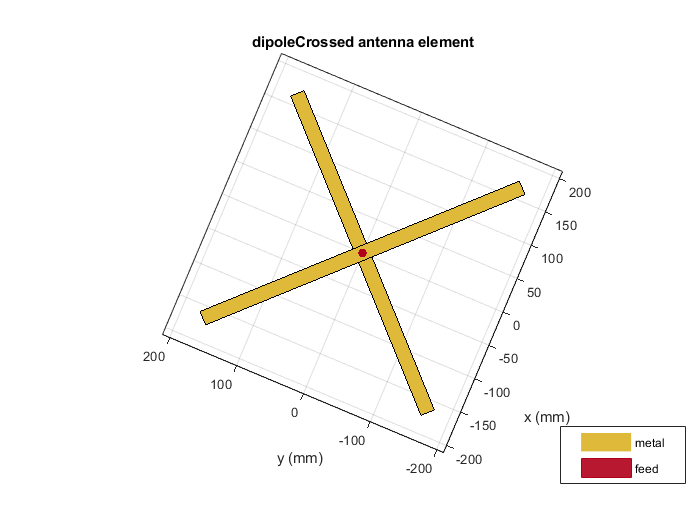

%Creating the antenna
Dip  = dipole('Length',length,'Width',width);
Antenna= dipoleCrossed('Element',Dip,'Tilt',90,'TiltAxis',[0 1 0]);
figure; show(Antenna);

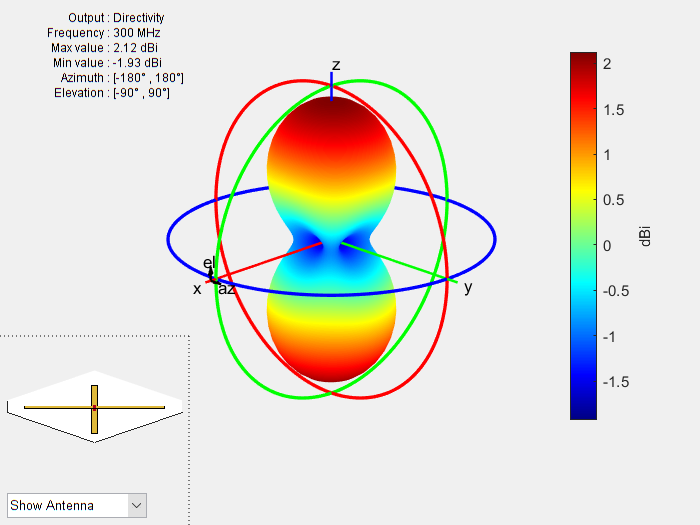

%The antenna Pattern
pattern(Antenna, freq);

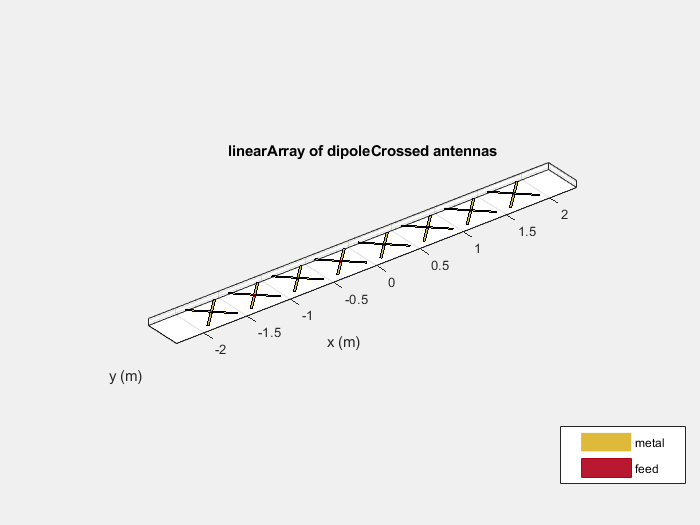

arr=linearArray('Element',Antenna,'ElementSpacing',spacing,'NumElements',8);
show(arr);

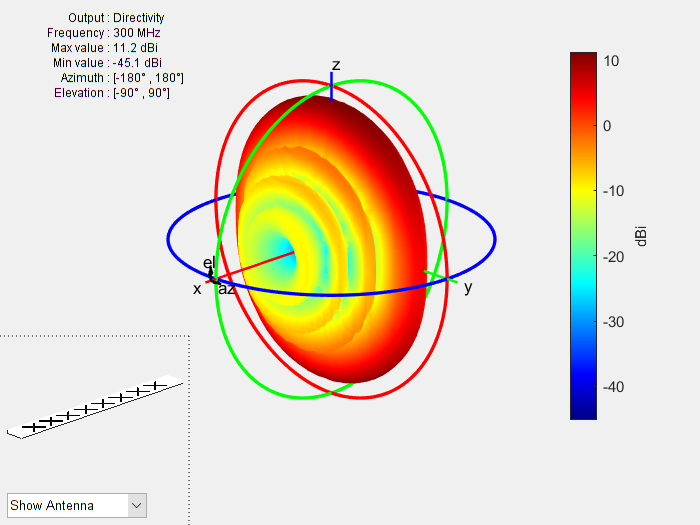

pattern(arr, freq);

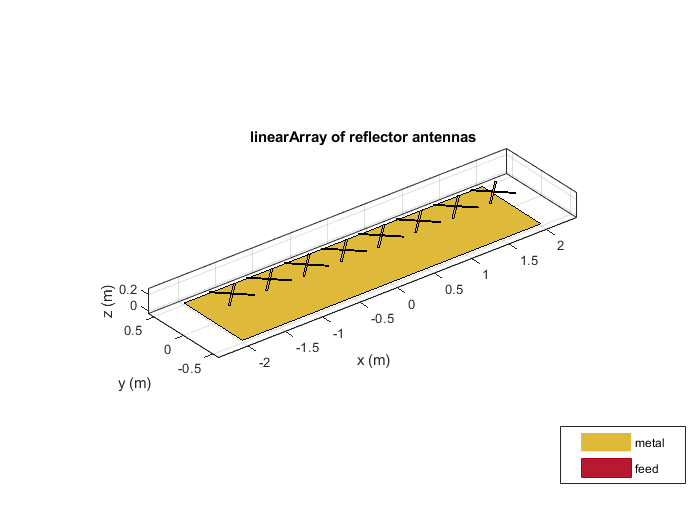

r = reflector('Exciter',Antenna,'GroundPlaneLength',spacing,              ...
    'GroundPlaneWidth', lambda,'Spacing',gndspacing);
refarray =linearArray('Element',r,'ElementSpacing',spacing,'NumElements',8);
show(refarray);

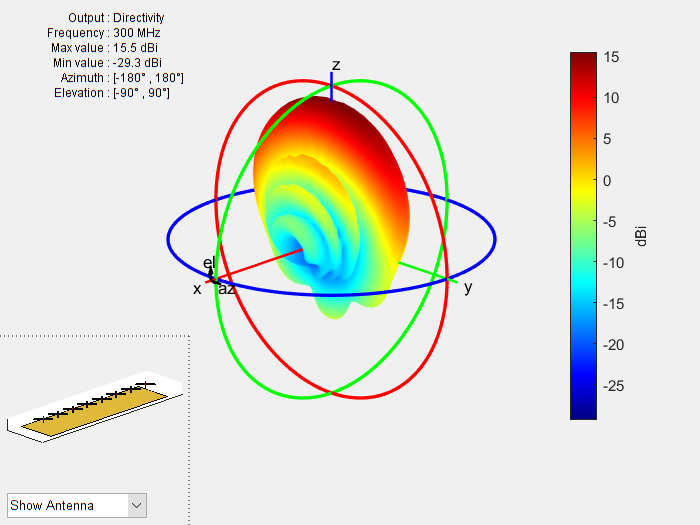

figure;
pattern(refarray, freq);

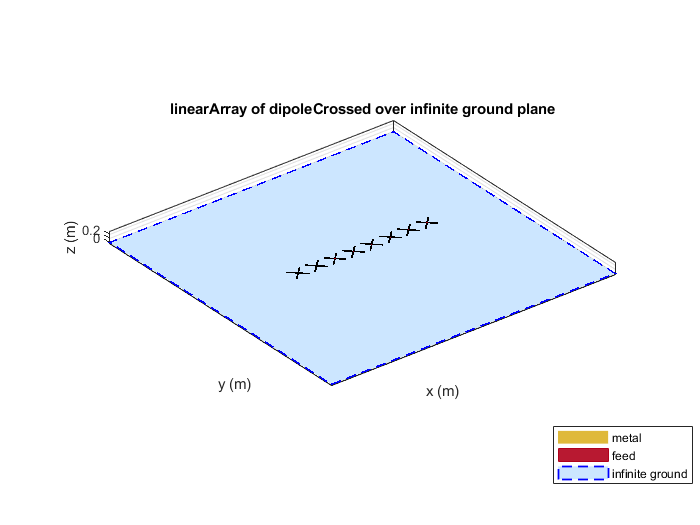

refarray.Element.GroundPlaneLength = inf;
show(refarray);

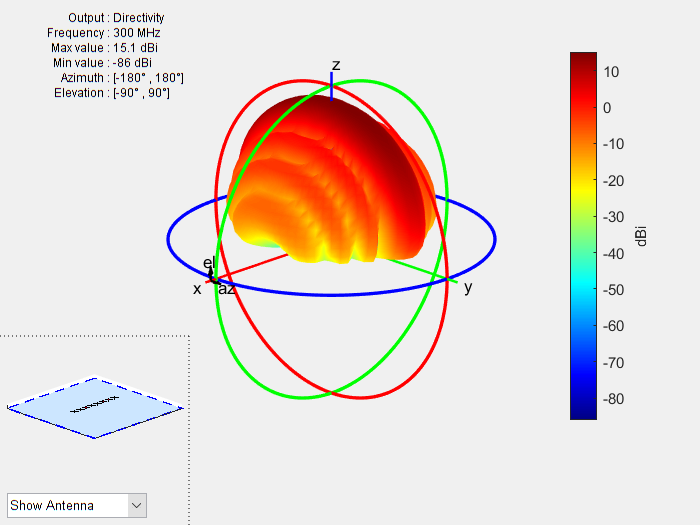

pattern(refarray, freq);